# Quickstart: Accessing Two-Photon Calcium Imaging Data from the Allen Brain Observatory

This example demonstrates quick access and basic analysis of the Visual Coding 2P dataset [1] from the Allen Brain Observatory [2] using the [Brain Observatory Toolbox](https://github.com/emeyers/Brain-Observatory-Toolbox) (BOT).

### Accessing the Visual Coding 2P Dataset

availSessions = bot.fetchSessions('ophys');

### Examining Sessions

#### Inspecting Available Sessions 

head(availSessions)

ans = 8×14 table
       id        experiment_container_id     stimulus_name     targeted_structure_acronym    fail_eye_tracking    imaging_depth        cre_line        date_of_acquisition                     name                     specimen_id    experiment_container      specimen      targeted_structure    well_known_files
    _________    _______________________    _______________    __________________________    _________________    _____________    ________________    ____________________    _____________________________________    ___________    ____________________

#### Select Sessions of Interest

% select experiments from the most orientation/direction-selective areas of visual cortex 
filteredSessions = availSessions(ismember(availSessions.targeted_structure_acronym, categorical(["VISal" "VISrl" "VISam"])), :);

% select experiments with GCaMP6f expression enriched in Layer 2/3 and Layer 4 of cortex
filteredSessions = filteredSessions(filteredSessions.cre_line == "Cux2-CreERT2", :);

% select experiments imaging from the shallowest depth in Layer 2/3
filteredSessions = filteredSessions(filteredSessions.imaging_depth == 175,:);

% select experiments with eye tracking data available
filteredSessions = filteredSessions(~filteredSessions.fail_eye_tracking, :);

% select experiments with drifting grating and natural movie stimuli
filteredSessions = filteredSessions(filteredSessions.stimulus_name == "three_session_A", :);
disp(filteredSessions)

       id        experiment_container_id     stimulus_name     targeted_structure_acronym    fail_eye_tracking    imaging_depth       cre_line       date_of_acquisition                       name                      specimen_id    experiment_container      specimen      targeted_structure    well_known_files
    _________    _______________________    _______________    __________________________    _________________    _____________    ______________    ____________________    ________________________________________    ___________    ____________________    

#### Creating Session Objects

sessionUnderStudy = bot.session(filteredSessions(1,:)); 
sessionUnderStudy.info    

ans = struct with fields:
                            id: 503412730
       experiment_container_id: 511510695
                 stimulus_name: three_session_A
    targeted_structure_acronym: VISal
             fail_eye_tracking: 0
                 imaging_depth: 175
                      cre_line: "Cux2-CreERT2"
           date_of_acquisition: 23-Feb-2016 19:10:20
                          name: "20160223_222425_3StimA"
                   specimen_id: 495727000
          experiment_container: [1×1 struct]
                      specimen: [1×1 struct]
            targeted_structure: [1×1 struct]
              well_known_files: [3×1 struct]


#### Inspecting Session Object Properties

disp(sessionUnderStudy)

  OphysSession with properties:

                                   info: [1×1 struct]
                                     id: 503412730
                           session_type: three_session_A
                            linkedFiles: [2×1 table]

   Linked File Values ('SessNWB')
                      cell_specimen_ids: '[on demand]'
          corrected_fluorescence_traces: '[on demand]'
                fluorescence_timestamps: '[on demand]'
                    fluorescence_traces: '[on demand]'
            fluorescence_traces_demixed: '[on demand]'
                fluorescence_traces_dff: '[on demand]'
                         max_projection: '[on demand]'
                      motion_correction: '[on demand]'
                             neuropil_r: '[on demand]'
                        neuropil_traces: '[on demand]'
                           nwb_metadata: '[on demand]'
                         

### Neuron Responses via Calcium Imaging Fluorescence Signals

timestamps = sessionUnderStudy.fluorescence_timestamps

timestamps = 115744×1 duration array
   9.9738 sec
   10.007 sec
    10.04 sec
   10.073 sec
   10.106 sec
    10.14 sec
   10.173 sec
   10.206 sec
   10.239 sec
   10.272 sec
   10.305 sec
   10.339 sec
   10.372 sec
   10.405 sec
   10.438 sec
   10.471 sec
   10.504 sec
   10.538 sec
   10.571 sec
   10.604 sec
   10.637 sec
    10.67 sec
   10.704 sec
   10.737 sec
    10.77 sec
   10.803 sec
   10.836 sec
   10.869 sec
   10.903 sec
   10.936 sec


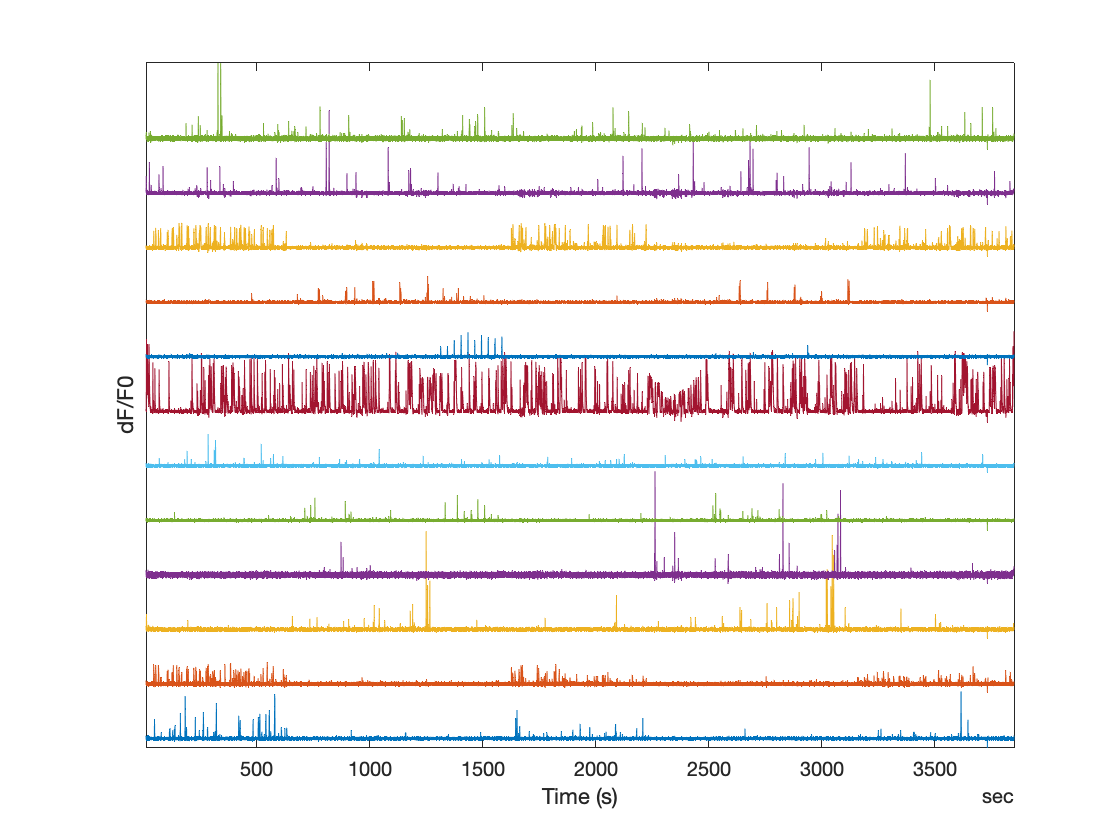

traces = sessionUnderStudy.fluorescence_traces_dff;
figure;
plot(timestamps, traces(:, 1:10:end) + (1:10:size(traces, 2))/3)
axis tight; xlabel('Time (s)'); set(gca, 'YTick', []); ylabel('dF/F0');

### Conclusion

In this quickstart, the use of basic methods and the access of object properties is illustrated with limited explanation. For more details about these methods and properties, see the ophys tutorial.

### References

[1] Copyright 2016 Allen Institute for Brain Science. Visual Coding 2P dataset. Available from: [http://portal.brain-map.org/explore/circuits/visual-coding-2p](http://portal.brain-map.org/explore/circuits/visual-coding-2p).

[2] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 